# Diffusion Smoothing

© 2017 Moo K. Chung

University of Wisconsin-Madison

**Diffusion smoothing** based on the finite element method (FEM) is introduced in [Chung et al (2001)](http://www.stat.wisc.edu/~mchung/papers/thesis.pdf). The `diffusion_smooth.m` routine requires `FEM.m` that computes A and C matrices associated with the FEM of the given surface mesh ([Chung & Taylor, 2004](http://www.stat.wisc.edu/~mchung/papers/BMI2004/diffusion_biomed04.pdf)). Instead of solving heat diffusion using FEM, it is possible to solve it as a spectral expansion of the Laplace-Beltrami operator ([Seo et al. 2010](http://www.stat.wisc.edu/~mchung/papers/miccai.2010.seo.pdf), [Seo & Chung, 2011](http://www.stat.wisc.edu/~mchung/papers/seo.2011.ISBI.pdf)). **Heat kernel smoothing** approach is more stable and robust. The code for heat kernel smoothing is given in [here.](http://brainimaging.waisman.wisc.edu/~chung/lb/) It is also possible to spectral expand heat kernel through the **fast polynomial approximation** ([Huang et al. 2019](http://pages.stat.wisc.edu/~mchung/papers/huang.2019.MICCAI.pdf), [Huang et al., 2020](https://pages.stat.wisc.edu/~mchung/papers/huang.2020.TMI.pdf)) in performing heat kernel convolution. The code for polynomial approximation is given [here](http://pages.stat.wisc.edu/~mchung/chebyshev/). The fast polynomial approximation is the fastest possible diffusion solver on manifolds.

Reference

[1] Chung, M.K. 2001. [Statistical Morphometry in Neuroanatomy](http://www.stat.wisc.edu/~mchung/papers/thesis.pdf), PhD Thesis, McGill University.

[2] Chung, M.K., Taylor, J. 2004. [Diffusion Smoothing on Brain Surface via Finite Element Method](http://www.stat.wisc.edu/~mchung/papers/BMI2004/diffusion_biomed04.pdf),  IEEE International Symposium on Biomedical Imaging (ISBI). 562.

[3] Seo, S., Chung, M.K., Vorperian, H. K. 2010. [Heat kernel smoothing using Laplace-Beltrami eigenfunctions](http://www.stat.wisc.edu/~mchung/papers/miccai.2010.seo.pdf). 13th International Conference on Medical Image Computing and Computer Assisted Intervention (MICCAI). Lecture Notes in Computer Science (LNCS). 6363:505-512.

[4] Seo, S., Chung, M.K. 2011. [Laplace-Beltrami eigenfunction expansion of cortical manifolds](http://www.stat.wisc.edu/~mchung/papers/seo.2011.ISBI.pdf). IEEE International Symposium on Biomedical Imaging (ISBI).

[5] Huang, S.-G., Lyu, I., Qiu, A., Chung, M.K. 2019. [Fast polynomial approximation to heat diffusion in manifolds](http://www.stat.wisc.edu/~mchung/papers/huang.2019.MICCAI.pdf)*, Medical Image Computing and Computer Assisted Intervention (MICCAI)* 11767:48-56. [MATLAB](http://brainimaging.waisman.wisc.edu/~chung/lb/)

[6]  Huang, S.-G., Lyu, I., Qiu, A., Chung, M.K. 2020. [Fast polynomial approximation of heat kernel convolution on manifolds and its application to brain sulcal and gyral graph pattern analysis](http://pages.stat.wisc.edu/~mchung/papers/huang.2020.TMI.pdf)*, IEEE Transactions on Medical Imaging* 39:2201-2212 [MATLAB](http://brainimaging.waisman.wisc.edu/~chung/lb/)

Update histrory: 2017 Page created in [http://brainimaging.waisman.wisc.edu/~chung/diffusion.](http://brainimaging.waisman.wisc.edu/~chung/diffusion.) 2026 Sept 6: Package moved to gitHub

##  Torus mesh

This example demonstrates diffusion smoothing on a triangulated torus. The simulated signal is defined on the mesh vertices and consists of the x-coordinate plus Gaussian random noise.

load torus
load signal

surf %torus surface mesh

surf = struct with fields:
    vertices: [3384×3 double]
       faces: [6768×3 double]


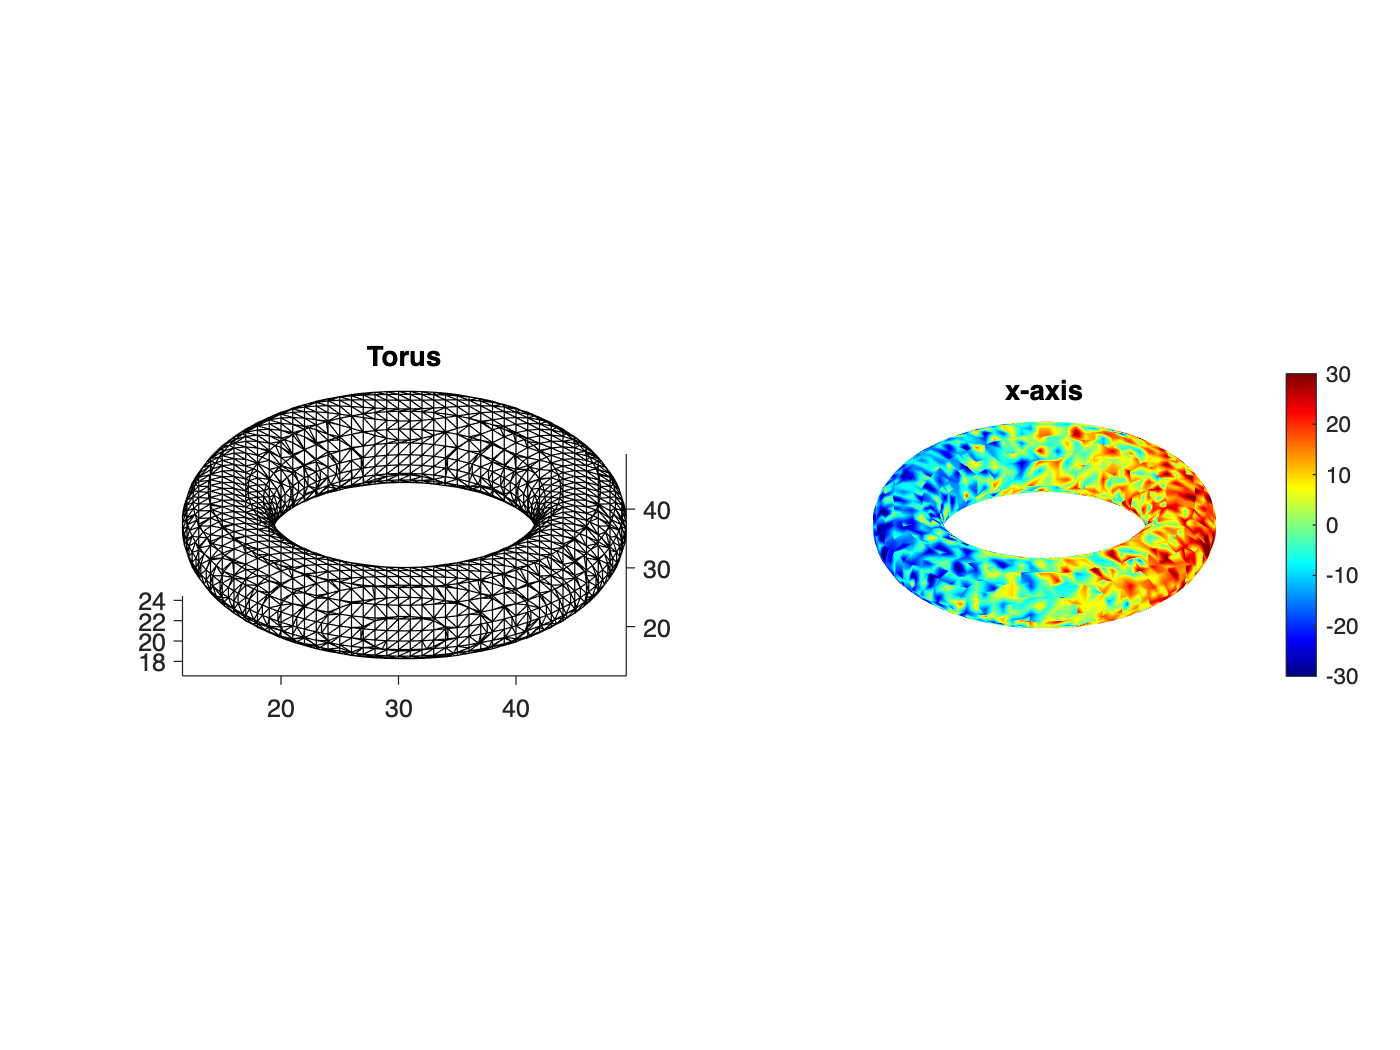

figure;
tiledlayout(1,2);

nexttile;
figure_wire(surf,'k','w')
view([0 30]);
title('Torus')
nexttile;

figure_surf(surf,signal);
colormap('jet');
colorbar;
view([0 30]);
caxis([-30 30]);
title('x-axis')

## Cotan finite element discretization

Construct the finite element matrices. `FEM.m` constructs the mass matrix A and stiffness matrix C associated with the finite element discretization of the Laplace-Beltrami operator. Additional details on the FEM construction is in [Chung & Taylor 2004](https://www.stat.wisc.edu/~mchung/papers/BMI2004/diffusion_biomed04.pdf). The mass matrix A represents integration over the surface. Its entries are determined by the areas of triangles incident to each mesh vertex. The stiffness matrix C represents the surface-gradient energy and is based on the cotangent weights of the triangular mesh. In the finite element formulation, the Laplace-Beltrami eigenvalue problem takes the generalized matrix form

$C \phi = \lambda A \phi$.

Both matrices are sparse because each vertex interacts only with vertices belonging to nearby triangles.

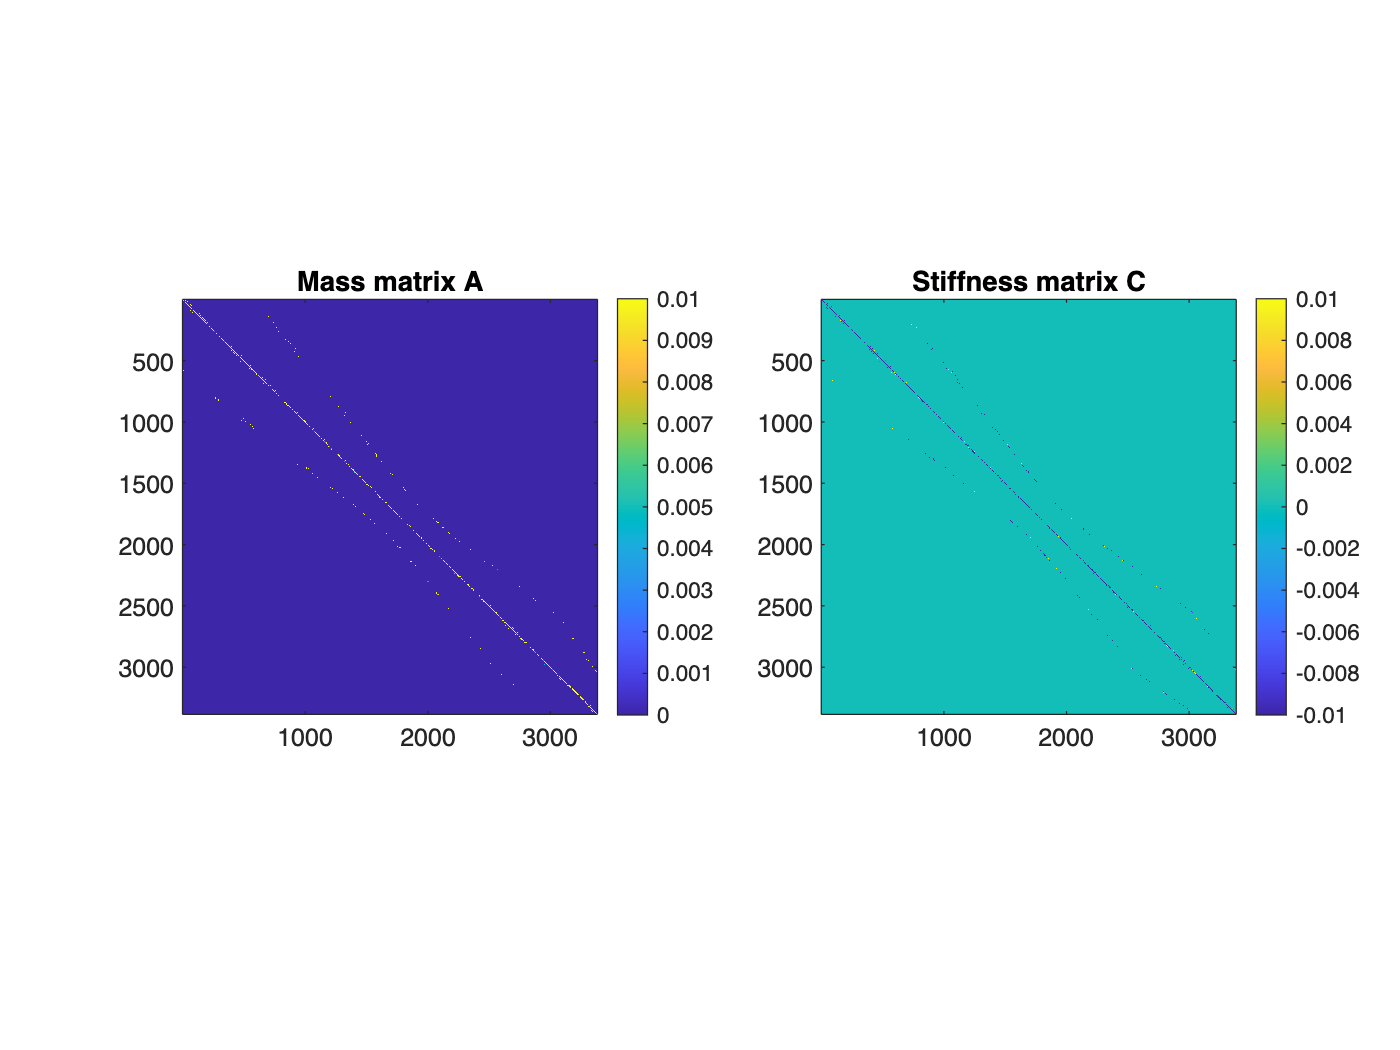

[A, C]= FEM(surf);

figure;
tiledlayout(1,2);
nexttile; imagesc(A) ;axis square; colorbar; caxis([0 0.01]); title('Mass matrix A')
nexttile; imagesc(C) ;axis square; colorbar; caxis([-0.01 0.01]); title('Stiffness matrix C')

## Diffusion smoothing

Diffusion smoothing is performed by numerically solving the heat equation on the triangulated surface using the finite element discretization of the Laplace--Beltrami operator. From the FEM mass matrix $A$ and stiffness matrix $C$, the discrete Laplace--Beltrami operator is given by


$$\Delta=-A^{-1}C.$$


The diffusion equation is solved using the explicit Euler iteration


$$f_{k+1} = f_k+\delta\Delta f_k,$$


where the numerical step size is $\delta=\frac{\sigma}{n}.$ Here, $\sigma$ determines the total amount of diffusion and $n$ is the number of iterations. Thus, for a fixed $\sigma$, increasing $n$ decreases the step size and improves numerical stability. For $\sigma=0.1$ and $n=100$, the step size is


$$\delta=\frac{0.1}{100}=0.001,$$


which produces a stable numerical solution. Increasing the diffusion parameter to $\sigma=1$ while keeping $n=100$ gives


$$\delta=\frac{1}{100}=0.01,$$


which is too large and results in numerical instability. Increasing the number of iterations to $n=1000$ reduces the step size to


$$\delta=\frac{1}{1000}=0.001,$$


and restores numerical stability while maintaining the same total diffusion parameter $\sigma=1$.

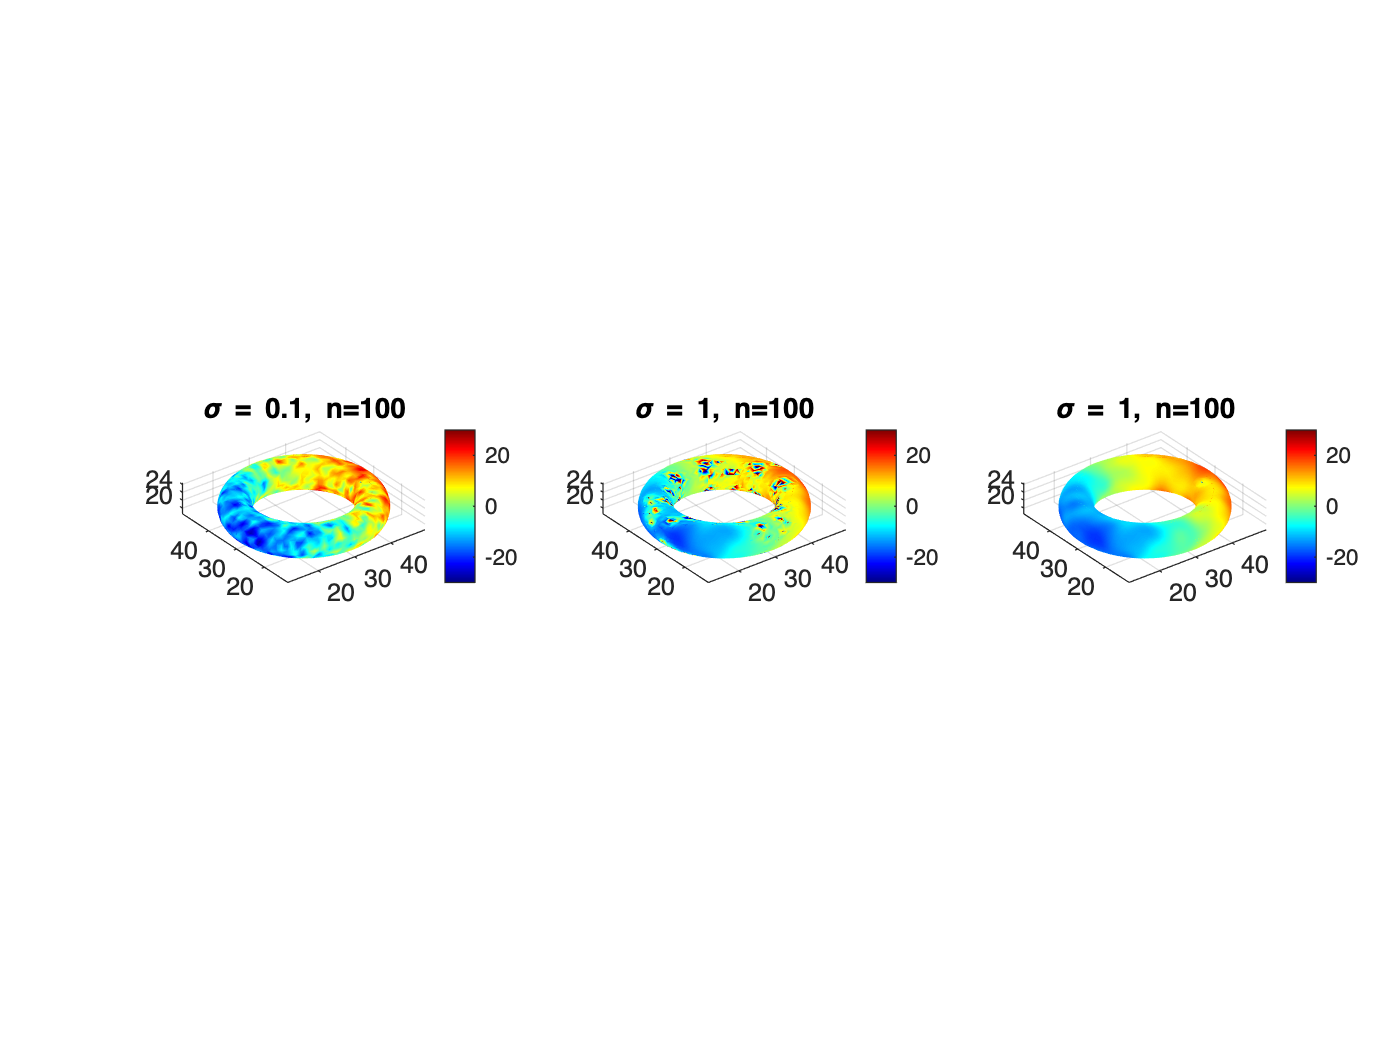

figure; tiledlayout(1,3);
nexttile;
smoothed= diffusion_smooth(signal, surf, 0.1, 100, A,C);
figure_surf(surf, smoothed);colormap('jet');colorbar; caxis([-30 30])
title('\sigma = 0.1, n=100')

nexttile;
smoothed= diffusion_smooth(signal, surf, 1, 100, A,C);
figure_surf(surf, smoothed);colormap('jet');colorbar; caxis([-30 30])
title('\sigma = 1, n=100')

nexttile;
smoothed= diffusion_smooth(signal, surf, 1, 1000, A,C);
figure_surf(surf, smoothed);colormap('jet');colorbar; caxis([-30 30])
title('\sigma = 1, n=1000')